# Maze solver

## Load the image of a Maze

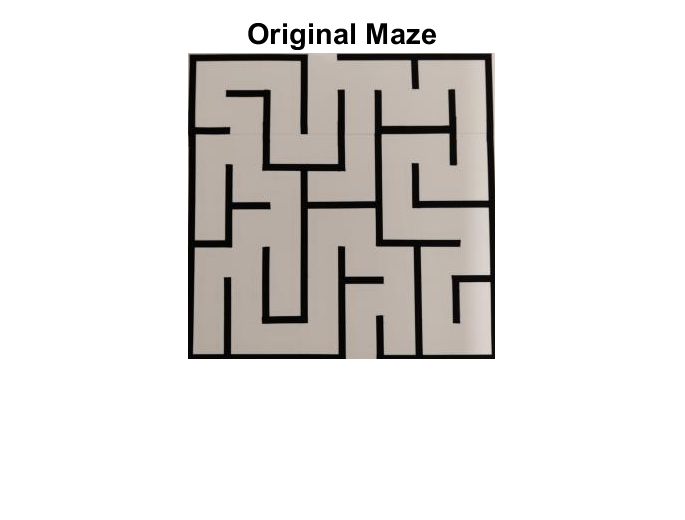

%Load in a maze image and display it on screen
maze = imread('realworld2.png'); 
imshow(maze);
title('Original Maze');

## Convert to binary image 

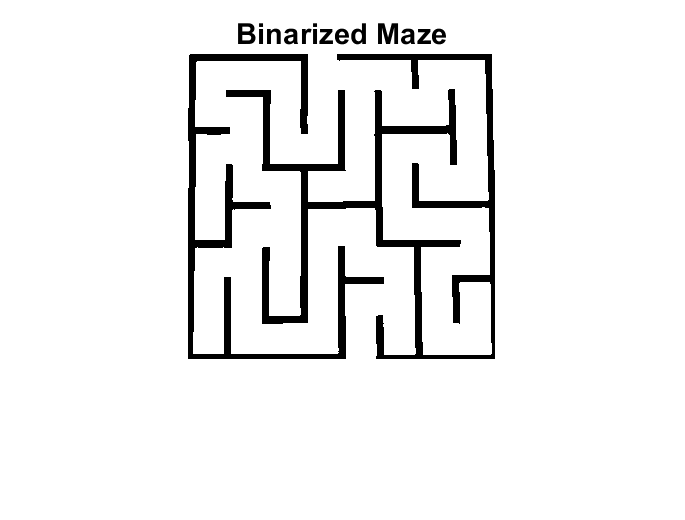

preBinaryMaze = rgb2gray(maze);
binaryMaze = imbinarize(preBinaryMaze,0.4);
imshow(binaryMaze);
title('Binarized Maze');

## Solve the maze

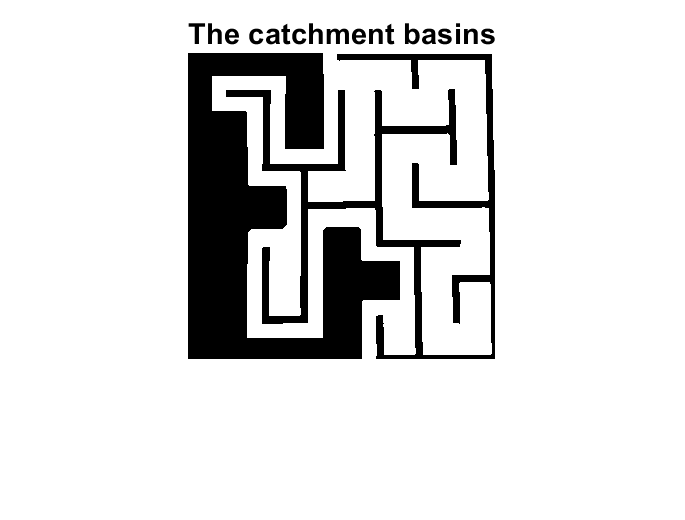

%Watershed transform to locoalize catchment basins
watershedMaze = watershed(binaryMaze);
cathcmenBasinOne = (watershedMaze == 2); 
highlightedCatchmenbasin = cathcmenBasinOne.*binaryMaze;
imshow(highlightedCatchmenbasin);
title('The catchment basins');

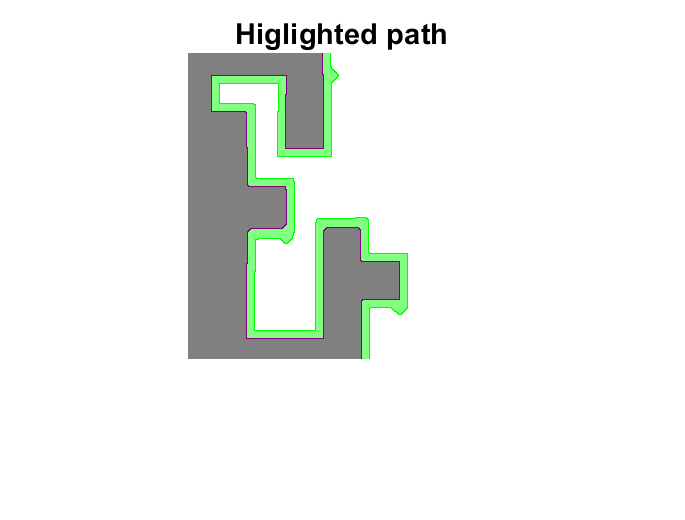


% Applying watershed to higlight border between the two parts
cathcmenBasinTwo = watershed(highlightedCatchmenbasin);
imshowpair(watershedMaze,cathcmenBasinTwo);
title('Higlighted path')


% Extract border based on the differnce of the two parts 
firstPart = watershedMaze;
secondPart = cathcmenBasinTwo;
path = firstPart - secondPart;

## Display the path

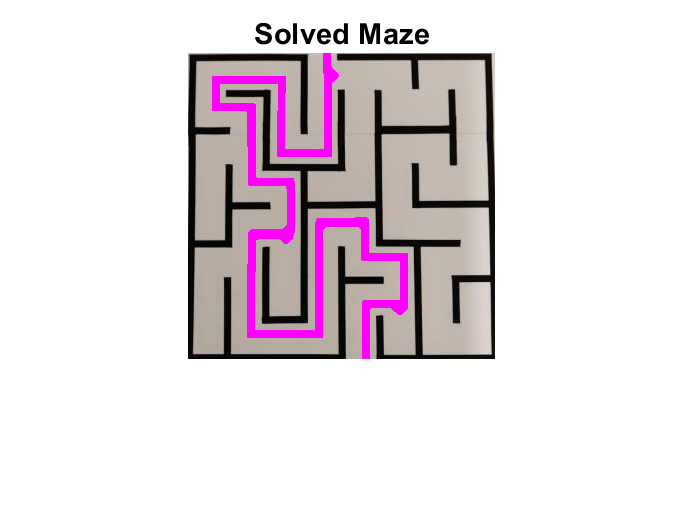

%Overlay solution over original maze Image and diplay it
Solved = imoverlay(path, maze, [1 0 1]); 
imshow(Solved);
title('Solution to maze')